clc, clear, close all

## Environment Properties

World.p = 1.225; % kg/m3
World.grip_scale = 0.8; 

## Load Track

Track = load("accel.mat");
Track.RWP = abs(1./Track.KWP);
if Track.start_from_zero
    Track.RWP(1) = 0.01;
end
Track.RWP(~isfinite(Track.RWP)) = 10000;

## Load Cars

Paddock(1).car = Car4W("car_01.json",...
                       "power_01.json",...
                       World);

## Use Walking Algorithm on Each Car

for i = 1:length(Paddock)
    disp("Calculating cornering velocities for Car "+i+" ...")
    VWP = cornVel(Paddock(i).car,Track.SWP,Track.RWP);
    disp("Done calculating cornering velocities for Car "+i+" ...")
    
    Log(i).VWP = VWP;

    disp("Walking points for Car "+i+" ...")
    [Log(i).MVWP,Log(i).GX,Log(i).GY] = walk(Paddock(i).car,Track.SWP,VWP,Track.RWP);
    disp("Done walking points for Car "+i+" ...")
    
    Paddock(i).laptime = lapTime(Track.SWP,Log(i).MVWP);
    Paddock(i).MVWP = Log.MVWP;
    fprintf("Car "+i+" completed track in %3.3f seconds.\n",Paddock(i).laptime);
    fprintf("\n");
end

Calculating cornering velocities for Car 1 ...


Done calculating cornering velocities for Car 1 ...


Walking points for Car 1 ...


100/100


Done walking points for Car 1 ...


Car 1 completed track in 5.597 seconds.


## Plot Results

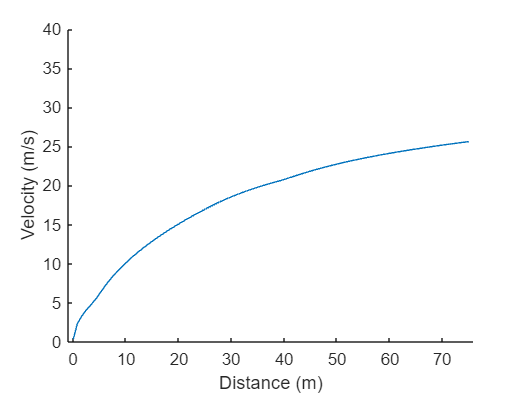

figure()
hold on
for i = 1:length(Paddock)
    plot(Track.SWP,Log(1).MVWP)
end
xlim([-1,Track.SWP(end)+1])
ylim([0,40])
xlabel("Distance (m)")
ylabel("Velocity (m/s)")

fprintf("Done!\n")

Done!
